sm = SessManager;
d = sm.cons_usable(sm.special_sessions_usable_index_single('Mouse2028'));
load(d.source_path);
X = tracesEvents.rawTraces;
%E = hyperdetect(X, 'z_val', 3, 'OutType', 'onset', 'Progress', true);
E = tracesEvents.events_transients;
S = tracesEvents.HD_spikes;

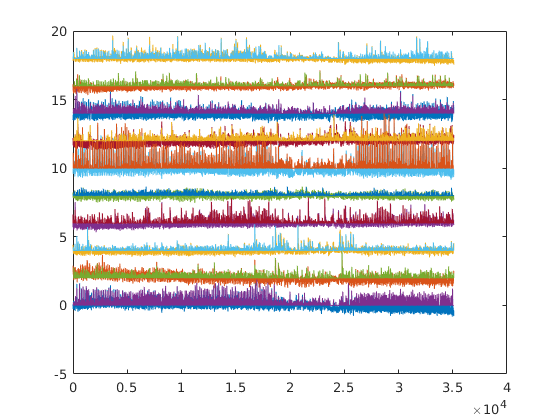

figure;

n_sel = 10;
idx = randperm(size(X,2), n_sel);
gaps = (0:n_sel - 1)*2;
X_sub = X(:, idx) + gaps;
E_sub = E(:, idx) + gaps;

plot(X_sub); hold on
plot(E_sub);

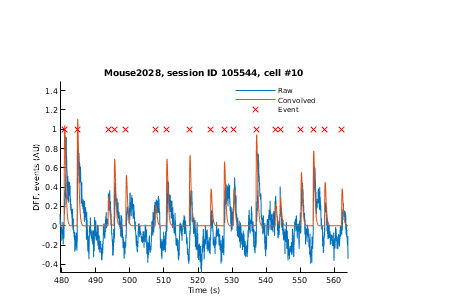

figure;
idx = 10;
T = size(X,1);
t = (1:T)*seconds(1/20);

x = X(:,idx); 

fac = 8;
e = E(:,idx) / fac;
s = S(:, idx) / fac;

plot(seconds(t), x);
hold on
plot(seconds(t), e);
%plot(t, s);
scatter(seconds(t(s~=0)), s(s~=0)~=0, 'xr');
xlabel 'Time (s)'
ylabel 'DFF, events (AU)'
%xlim([duration(0,6,24.4)...
%      duration(0,6,56.0)])
%ylim([-0.58 1.11])
xlim(seconds([duration(0,7,59.5)...
      duration(0,9,24.0)]))
ylim([-0.49 1.5])
title 'Mouse2028, session ID 105544, cell #10';
legend 'Raw' 'Convolved' 'Event' Location best
legend box off
set(gca, 'Box', 'off');
figure_format([3 2]);
Utils.printto('events_figs/sta', 'event_detect_demo.pdf');

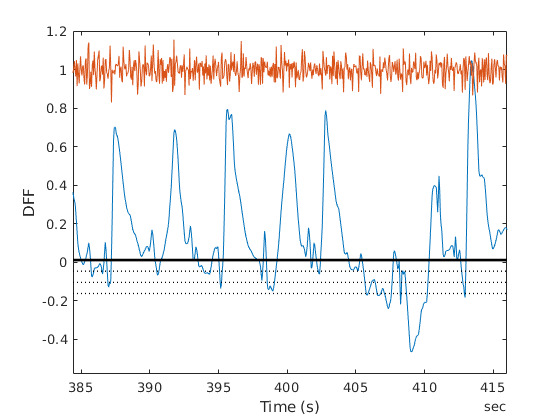

figure;
tr = x;
tr_dn = wdenoise(tr);
noise = tr - tr_dn;
sigma = std(noise);

z_val = 3;
min_mag = z_val * sigma;

pct = prctile(tr_dn, 25);
peak_th = pct + min_mag;

plot(t, tr_dn);
hold on;
plot(t, noise + 1);

line(xlim, [pct pct], 'Color', 'k', 'LineWidth', 1, 'LineStyle', ':');
line(xlim, [pct+sigma, pct+sigma], 'Color', 'k', 'LineWidth', 1, 'LineStyle', ':');
line(xlim, [pct+2*sigma, pct+2*sigma], 'Color', 'k', 'LineWidth', 1, 'LineStyle', ':');
line(xlim, [peak_th peak_th], 'Color', 'k', 'LineWidth', 2);

xlim([duration(0,6,24.4)...
      duration(0,6,56.0)])
ylim([-0.58 1.2])

xlabel 'Time (s)'
ylabel DFF

my_opt.numStdsForThresh = 0.5;
[signalPeaks, signalPeaksArray, signalSigmas] = computeSignalPeaks(X.', 'options', my_opt);

calculating signal peaks...


E_b = signalPeaks.';

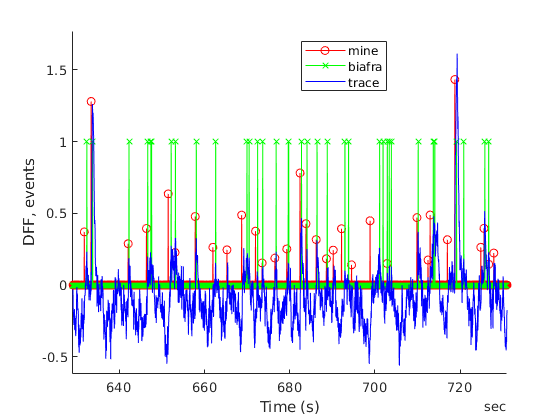

ix = 123;

figure;

hold on
plot(t, E(:, ix), '-or');
plot(t, E_b(:, ix), '-xg');
plot(t, X(:,ix), 'b');
xlabel 'Time (s)'
ylabel 'DFF, events'

xlim([duration(0,10,29.1)...
      duration(0,12,11.0)])
ylim([-0.62 1.77])
legend mine biafra trace Location best

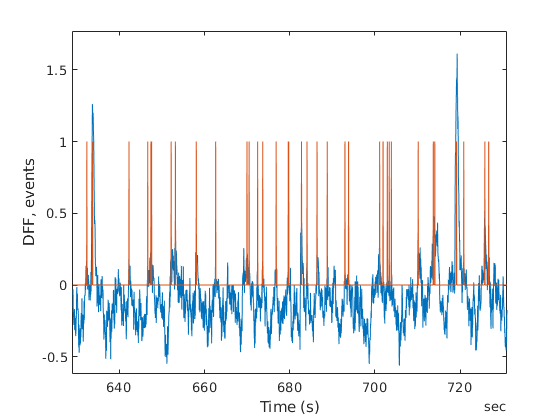

ix = 123;

figure;
plot(t, X(:,ix));
hold on
plot(t, E_b(:, ix));
xlabel 'Time (s)'
ylabel 'DFF, events'

xlim([duration(0,10,29.1)...
      duration(0,12,11.0)])
ylim([-0.62 1.77])

sm = SessManager;
d = sm.cons_usable(sm.special_sessions_usable_index_single('Mouse2022'));
load(d.source_path);
X = tracesEvents.events_transients;

ixs = 1:33:497;

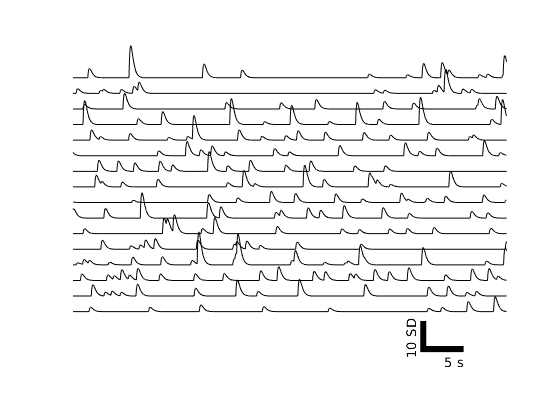

figure;
t_idx = 1001:2000;
t = (t_idx - t_idx(1))/20;
offset = (0:numel(ixs)-1)*5;
plot(t, X(t_idx,ixs) + offset, 'k');
ylim([-20 90]);
rectangle('Position', [40 -13 5 2], 'FaceColor', 'k', 'EdgeColor','none');
text(45, -16, '5 s', 'HorizontalAlignment',"right");
rectangle('Position', [40 -13 0.7 10], 'FaceColor','k', 'EdgeColor','none');
text(40, -15, '10 SD', 'VerticalAlignment',"bottom", 'Rotation',90);
axis off
Utils.printto('events_figs/sta', 'event_traces.pdf');